# KF tuning with fminsearch optimization

The search variables $x_1 ,x_2$ are the exponents of $q_i =e^{x_1 }$ and $q_F =e^{x_2 }$ to ensure positiveness

clc
clf
clear all
close all
rng(0)

## Load data

data = load('KF_TuningData.mat').out';

## Initialize

qi_init = 1e-5;
qF_init = 1e-5;
x_init = log([qi_init, qF_init]);

## Cost function wrapper

do_plot = false;
obj_fcn = @(u) KF_simulate(struct('qi', exp(u(1)), 'qF', exp(u(2))), data, do_plot);

## Optimize

options = optimset('Display', 'iter', ...
                   'TolFun', 1e-10, ...
                   'TolX', 1e-10, ...
                   'MaxIter', 1000);

tic
[x_opt, cost_min] = fminsearch(obj_fcn, x_init, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1      8.08664e-05         
     1            3      8.08664e-05         initial simplex
     2            5      6.18339e-05         expand
     3            7      4.53684e-05         expand
     4            9      2.33623e-05         reflect
     5           11      1.60973e-05         reflect
     6           13      1.60973e-05         contract inside
     7           14      1.60973e-05         reflect
     8           16      1.60973e-05         contract inside
     9           18      1.56244e-05         contract inside
    10           20      1.55627e-05         contract outside
    11           22      1.55627e-05         contract inside
    12           24      1.55627e-05         contract inside
    13           26      1.52729e-05         expand
    14           27      1.52729e-05         reflect
    15           29      1.43195e-05         expand
    16           31      1.29651e-05         expa

toc

Elapsed time is 35.293842 seconds.



qi_opt = exp(x_opt(1));
qF_opt = exp(x_opt(2));
fprintf('%.10f', qi_opt)

6437996.4942364497

fprintf('%.10f', qF_opt)

17591.2698645677

## Plot resulting filtering

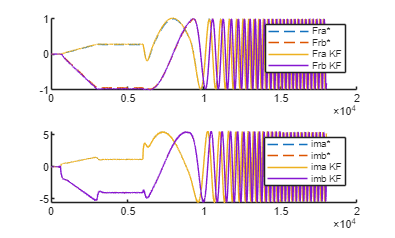

ans = 5.2510e-08

x = struct();
x.qi = qi_opt;
x.qF = qF_opt;
do_plot = true;
KF_simulate(x, data, do_plot)